#### Progetto MATLAB 

Kilian Tiziano Le Creurer 

Matricola 934596.

#### Introduzione

Il progetto mira ad eseguire un analisi statistica dei dati ricavati dal sito www.numbeo.com, i quali sono consistono in  tabelle contenenti indici numerici riguardanti la situazione economica e sociale di oltre 100 nazioni del mondo.

In particolare si studieranno gli indici che a mio parere rappresentano maggiormente il benessere di una Nazione, in un interavallo di 10 anni (dal 2012 ad oggi), per circa un centinaio di nazioni del mondo con l'obiettivo di mostrare, attraverso grafici  MATLAB, le variazioni (se presenti)  degli stessi indici.

Il progetto si divide in tre fasi:

- Web scraping

- Preprocessing dei dati

- Analisi 

#### Web Scraping

Gli indici da analizzare si trovano in tabelle identiche, una per ogni anno, sul sito [https://www.numbeo.com](https://www.numbeo.com) .Per poterci lavorare è necessario che vengano scaricati su tabelle in MATLAB,  cosi da poter poi essere manipolati a analizzati.

Inoltre siccome sono interessato agli andamenti progressivi negli anni delle features inserirò l'anno corrispondente ad ogni misurazione come variabile della tabella finale.




url='https://www.numbeo.com/quality-of-life/rankings_by_country.jsp?title=';
T=table; %inizializzo una tabella che conterrà tutti gli indici;
i=0;
for yyear=2012:2021  %inizializzo il ciclo con il primo anno che voglio nella tabella
%... Poichè gli url dove si trovano gli indici differiscono soltanto per
%... l'anno, apparte gli ultimi 2 che dopo l'anno hanno anche una stringa "-Q1", che si trova alla fine del testo, concateno alla stringa url la stringa
%... anno.
if(i<2)
url1=strcat(url,string(yyear),"-Q1");
else 
url1=strcat(url,string(yyear));
end
i=i+1;
html=webread(url1); %leggo il contenuto della pagina
%...A questo punto è necessario analizzare il codice html dell'url che sto
%...considerando,si nota immediatamente che tutti gli indici che voglio 
%...scaricare si trovano in una tabella html, 
%...quindi la parola chiave che mi interessa ricavare è 'tr'.
parsed_html=htmlTree(html); 
key_word='tr'; 
table_datas=findElement(parsed_html,key_word); %cerco gli elementi dell'html che siano righe di una tabella
%...Elimino i primi due elementi della tabella in quanto
%...contengono soltanto indicazioni grafiche sulla tabella e i titoli
%...degli elementi.
table_datas(1)=[];
table_datas(1)=[];
n_righe=numel(table_datas); 


%...Inizializzo le variabili che voglio inserire nella tabella,considerando solo
%...gli indici che voglio usare per analizzare i dati
nazione=cell(n_righe,1);
sicurezza=zeros(n_righe,1);
salute=zeros(n_righe,1);
costo_della_vita=zeros(n_righe,1);
prop_su_stip=zeros(n_righe,1);
inquinamento=zeros(n_righe,1);
clima=zeros(n_righe,1);
anno=zeros(n_righe,1)+yyear; 
%... Creo una variabile anno che aggiungo alla tabella
%... per poter poi graficare degli andamenti 

%...Estraggo il contenuto riga per riga
for ii=1:n_righe
    riga=findElement(table_datas(ii),'td'); %estraggo tutti gli elementi colonna della riga ii-esima
    nazione{ii}=char(extractHTMLText(riga(2)));
    sicurezza(ii,1)=double(extractHTMLText(riga(5)));
    salute(ii,1)=double(extractHTMLText(riga(6)));
    costo_della_vita(ii,1)=double(extractHTMLText(riga(7)));
    prop_su_stip(ii,1)=double(extractHTMLText(riga(8)));
    inquinamento(ii,1)=double(extractHTMLText(riga(10)));
    clima(ii,1)=double(extractHTMLText(riga(11)));
end

%...Creo la tabella con le variabili che mi interessano
T_temp=table(nazione,anno,sicurezza,salute,costo_della_vita,prop_su_stip,inquinamento,clima);
T_temp.Properties.VariableNames={'Nazione','Anno','Sicurezza','Salute','Costo della vita','Potere d"acquisto immobiliare'...
    ,'Inquinamento','Clima',};
%...Concateno le righe della tabella i-esima con la tabella finale
T=[T;T_temp]; 
%... Ho scelto di non preallocare la memoria a T per semplificare il
%... codice, infatti evito di inserire a mano le lunghezze della varie
%... tabelle, o di usare due cicli.
%...  
end

#### Data Preprocessing

Ora ho una tabella che contiene informazioni riguardanti salute, costo della vita, potere d'acquisto immobiliare, sicurezza, inquinamento e clima, inoltre in ogni riga della tabella ho anche l'anno corrispondente

%...Per prima cosa creo una cartella dove salvare la tabella, 
%...in modo da non dover eseguire lo scraping dei dati tutte le volte che ci lavoro sopra
folder_name = 'dataset_quality_of_life';
if ~exist(folder_name,'dir')
    mkdir (folder_name);
end
%... Salvo la tabella 
writetable(T,"dataset_quality_of_life/index.csv");

%... Creo una sezione per caricare la tabella dal csv
addpath ('dataset_quality_of_life')
T=import_tab("index.csv");
rmpath('dataset_quality_of_life')

head(T)

ans = 8×8 table
          Nazione           Anno    Sicurezza    Salute    CostoDellaVita    PotereDacquistoImmobiliare    Inquinamento    Clima
    ____________________    ____    _________    ______    ______________    __________________________    ____________    _____

    Switzerland             2012      74.22      79.51         148.69                   6.53                  35.49         NaN 
    Germany                 2012       78.8      71.96          92.83                    4.8                  45.14         NaN 
    Norway                  2012      80.93      79.04         166.65                    7.1                  19.22         NaN 
    United Arab Emirates    2012      64.05      63.89          80

Per poter analizzare i dati è necessario capire, almeno in prima battuta che significato hanno gli indici che voglio analizzare, migliorando così la conoscenza del dominio in esame.

In particolare devo tenere in conto ciò che ogni indice rappresenta, ad esempio 'Inquinamento' e 'Clima' hanno un significato positivo quando sono bassi/decrescono.

%...Per iniziare creo un vettore con tutte le nazioni in modo unico, 
%...e un corrispondente vettore che mi indica quante volte una Nazione si trova nella tabella
[presenze,nazioni]=groupcounts(T.Nazione);

Ci sono 92 Nazioni in totale nel dataset.

Metto gli elementi in ordine alfabetico per Nazione e in ordine di anno successivamente.

T=sortrows(T); 
head(T)

ans = 8×8 table
     Nazione     Anno    Sicurezza    Salute    CostoDellaVita    PotereDacquistoImmobiliare    Inquinamento    Clima
    _________    ____    _________    ______    ______________    __________________________    ____________    _____

    Argentina    2012      51.62      76.74         68.05                   11.83                     90          NaN
    Argentina    2013      40.71      78.26         69.68                   10.19                  55.56          NaN
    Argentina    2014      42.52      76.75         66.85                    8.95                  57.45          NaN
    Argentina    2015       37.6      75.18         67.12                   11.59                  55.88          NaN
   

Osservando il vettore presenze mi accorgo che molti Paesi hanno gli indici calcolati solo per pochi anni, è chiaro che per mostrare un' evoluzione temporale ho bisogno di un minimo numero di osservazioni, per cui elimino dalla tabella tutte le Nazioni con meno di 6 osservazioni, così da lavorare con solo i dati che mi interessano.

nazioni_da_eliminare=presenze<6;
n_naz_da_eliminare=sum(nazioni_da_eliminare,'all');
nazioni=nazioni(nazioni_da_eliminare);
T(ismember(T.Nazione,nazioni),:)=[];

%...Controllo quante nazioni sono rimaste
[presenze,nazioni]=groupcounts(T.Nazione);
%...Sono rimaste 64 Nazioni con osservazioni per almeno 6 anni.


Inizio il prepocessing vero e proprio dei dati osservando se ci sono dei dati mancanti.

missing_data = ismissing(T);
%... Controllo in che modo sono suddivisi i vari missing data
miss_order=sum(missing_data)

miss_order =      0     0     0     0     0     0     0   236


Si trovano tutti sull'ultima riga, quella dove c'è l'indice sul clima

Osservando meglio il dataset emerge immediatamente che gli indici climatici sono assenti dal 2012 al 2015, opto per lasciare i missing data nella tabella tenendone poi conto quando calcolerò delle statistiche

Non conoscendo bene la natura con cui i valori degli indici sono ottenuti è impossibile poter valutare gli outlier, perciò tutti i valori presenti verrano considerati validi. 

#### Analisi

Per poter costruire il plot delle features voglio costruire due variabili distinte che contengeno una le informazioni sugli indici per i quali una crescita è positiva (Sicurezza, Salute, ecc) e l'altra quelle per gli indici la cui crescita è un dato negativo (Inquinamento ,Clima).

Dopodichè unirò le variazioni con significato positivo e quelle con significiato negativo, semplicemente facendone la media.

Ogni operazione nel ciclo viene svolta per le variazioni a cui do un significato positivo e per quelle a cui lo do negativo.


%...Inizializzo l'indice e il vettori con le differenze assolute (una per i
%...positivi e un per i negativi)
table_index=0;
diff_max_minp=zeros(length(presenze),1);
diff_max_minn=zeros(length(presenze),1);
%...Inizializzo una matrice che conterrà i valori medi degli indici per
%...ogni osservazione
quality_of_lifep=zeros(length(T.Nazione),1);
quality_of_lifen=zeros(length(T.Nazione),1);
%...Creo 2 tabelle senza la variabile anno per calcolare la media dei
%...soli indici (una per i positivi e una per i  negativi)
Tp=T(:,["CostoDellaVita","Sicurezza","PotereDacquistoImmobiliare","Salute"]);
Tn=T(:,["Clima","Inquinamento"]);

%...Poichè le medie degli indici sono decisamente diverse fra loro per
%...determinare le variazioni complessive dettate da più indici normalizzo
%...entrambi i miei vettori
Tp=normalize(table2array(Tp(:,vartype('numeric'))));
Tn=normalize(table2array(Tn(:,vartype('numeric'))));
for ii=1:length(presenze)
%...Inizializzo i vettori di valori medi, dove inserirò anche l'anno
%...corrispondente così da sapere se la variazione è una crescita o il
%...contrario
valuep_array=zeros(presenze(ii),2); %questi vettori conterranno i valori medi degli indici per ogni anno e l'anno corrispondente
valuen_array=zeros(presenze(ii),2);
    for jj=1:presenze(ii) %ciclo per ogni nazione, percorre tutte le osservazioni.
%...Aggiorno l'indice con il numero di occorrenze dell'ii-esima nazione
table_index=table_index+1;
%...Calcolo la media degli indici per la nazione i-esima nel jj-esimo
%...anno
%...Aggiorno le nuove variabili ( media degli indici positivi e media degli
%...indici negativi
quality_of_lifep(table_index,:)=mean(Tp(table_index),"omitnan");
quality_of_lifen(table_index,:)=mean(Tn(table_index),"omitnan");

valuep_array(jj,1)=quality_of_lifep(table_index);
valuep_array(jj,2)=T.Anno(table_index);

valuen_array(jj,1)=quality_of_lifen(table_index);
valuen_array(jj,2)=T.Anno(table_index);
    end
%...Calcolo la differenza fra massimo e minimo per la nazione
%...presenze(ii)-esima, chiedendo anche l'indice così da ricavere inditro
%...anche l'anno corrispondente
[maximump,i_maxp]=max(valuep_array);
[minimump,i_minp]=min(valuep_array);

[maximumn,i_maxn]=max(valuen_array);
[minimumn,i_minn]=min(valuen_array);

%...Metto in luce un segno che è postivo se il massimo si trova
%...temporalmente dopo il minimo è negativo viceversa. (per le crescite
%...positive)
if((valuep_array(i_maxp(1,1),2)-valuep_array(i_minp(1,1),2))>0)
grouthp=1;
else 
grouthp=-1;
end


%...Eseguo l'operazione inversa per le variazioni negative
if((valuen_array(i_maxn(1,1),2)-valuen_array(i_minn(1,1),2))>0)
grouthn=-1; %in questo modo in entrambi i casi associo al segno + il significato positivo nel senso degli indici
else 
grouthn=1;
end
%...Calcolo la differenza fra valore massimo e minimo con segno, se il
%...massimo è temporalmente dopo il minimo segno positivo, altrimenti negativo
diff_max_minp(ii)=(maximump(1,1)-minimump(1,1))*grouthp;    

diff_max_minn(ii)=(maximumn(1,1)-minimumn(1,1))*grouthn;
end

Praticamente per ogni nazione ho costruito una nuova variabile che mi fornisce un indicazione su quanto i valori degli indici sono variati negli anni e su quanto la variazione ha un signficato positivo.

In particolare un valore positivo signfica che la qualità della vita è in crescita, un valore negativo il contrario.

%...Questa variabile mi da un indicazione con segno sulla variazione massima
%...che una nazione ha ottenuto
diff_max_min_medium=(diff_max_minn+diff_max_minp)/2;
Table_variations=table(nazioni,diff_max_min_medium);
Table_variations.Properties.VariableNames={'Nazioni','Crescita'};
valore_medio=mean(diff_max_min_medium)

valore_medio = -1.0510

massimo=max(diff_max_min_medium)

massimo = -0.0363

Il risultato è piuttosto scoraggiante, secondo questi risultati non c'è nemmeno una Nazione fra le 64 prese in considerazione che ha un complessivo andamento degli indici positivo.

Discretizzo infine la variabile che ho creato per incasellare tutte le Nazioni

bins = linspace(min(diff_max_min_medium),max(diff_max_min_medium),4);
Table_variations.Crescita= discretize(Table_variations.Crescita,bins);
Table_variations.Crescita = categorical(Table_variations.Crescita);
Table_variations.Crescita = renamecats(Table_variations.Crescita,...
categories(Table_variations.Crescita), ["Costante", "Leggermente negativa","Disastrosa"]);
[conteggio,evoluzione]=groupcounts(Table_variations.Crescita)

conteggio =      4
    21
    39


evoluzione = 3×1 categorical array
     Costante 
     Leggermente negativa 
     Disastrosa 


Solamente 4 Nazioni hanno un andamento che rientra nella categoria costante, mentre sono ben 39 quelle che ne hanno uno disastroso.

Ora voglio sfruttare la variabile  per eseguire i plot indice per indice delle Nazioni che hanno evoluzione costante e di quelle con un andamento disastroso più netto

%...Identifico le 5 Nazioni con un andamento "buono"
[diff_pos,id_pos]=maxk(diff_max_min_medium,5);
%...
[diff_neg,id_neg]=maxk(diff_max_min_medium*(-1),5);
%...Conservo gli indici così so quali a quali nazioni appartengono
nazioni_pos=nazioni(id_pos);
nazioni_neg=nazioni(id_neg);
%...Creo una sotto-tabella con solo le 10 Nazioni che voglio considerare
T_pos=T;
T_neg=T;
T_pos(~ismember(T.Nazione,nazioni_pos),:)=[];
T_neg(~ismember(T.Nazione,nazioni_neg),:)=[];

Adesso ho ottenuto una tabella con solo le nazioni che voglio considerare, ovvero quelle con uno scarto più estremo fra minimo e massimo, per cui cui posso graficarle con degli scatter plot.

[presenze_pos,nazioni_pos]=groupcounts(T_pos.Nazione);
[presenze_neg,nazioni_neg]=groupcounts(T_neg.Nazione);

Procedo con gli scatter plot

Prima osservo i 5 trend positivi per ogni variabile.

1) Salute

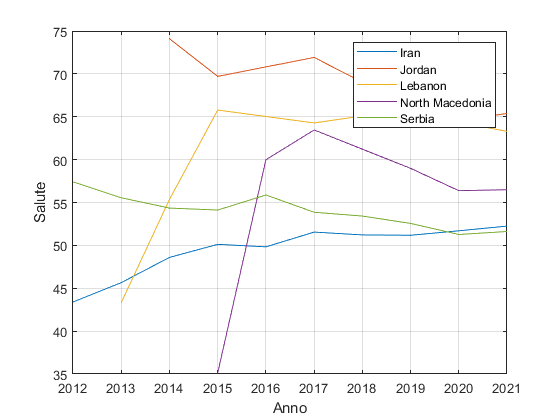

plot(T_pos.Anno(1:presenze_pos(1)),T_pos.Salute(1:presenze_pos(1)))
grid on
hold on
%...Inizializzo l'indice della nuova tabella a 10 cosi tengo conto della prima
%...osservazione
table_2_index=presenze_pos(1);
%...Inizializzo una variabile con il numero di osservazioni
for ii=2:length(nazioni_pos)
plot(T_pos.Anno(table_2_index+1:table_2_index+presenze_pos(ii)),T_pos.Salute(table_2_index+1:table_2_index+presenze_pos(ii)))
%...Aggiorno l'indice della tabella
table_2_index=table_2_index+presenze_pos(ii);
xlabel("Anno")
ylabel("Salute")
end
hold off
legend(string(nazioni_pos));

2) Inquinamento

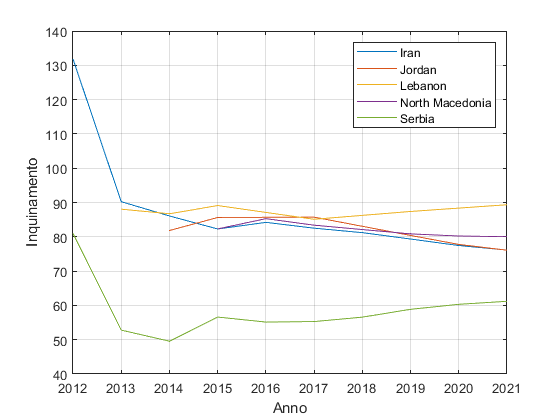

plot(T_pos.Anno(1:presenze_pos(1)),T_pos.Inquinamento(1:presenze_pos(1)))
grid on
hold on
%...Inizializzo l'indice della nuova tabella a 10 cosi tengo conto della prima
%...osservazione
table_2_index=presenze_pos(1);
%...Inizializzo una variabile con il numero di osservazioni
for ii=2:length(nazioni_pos)
plot(T_pos.Anno(table_2_index+1:table_2_index+presenze_pos(ii)),T_pos.Inquinamento(table_2_index+1:table_2_index+presenze_pos(ii)))
%...Aggiorno l'indice della tabella
table_2_index=table_2_index+presenze_pos(ii);
xlabel("Anno")
ylabel("Inquinamento")
end
hold off
legend(string(nazioni_pos));

3) Clima

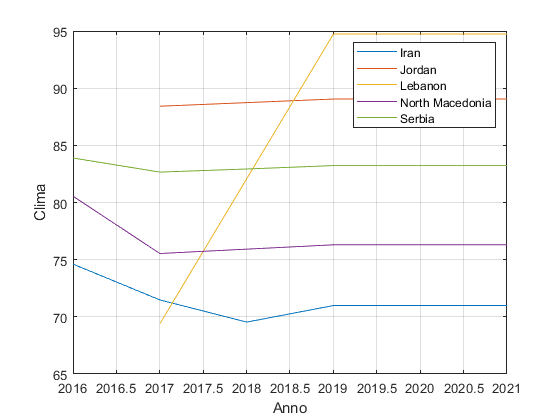

plot(T_pos.Anno(1:presenze_pos(1)),T_pos.Clima(1:presenze_pos(1)))
grid on
hold on
%...Inizializzo l'indice della nuova tabella a 10 cosi tengo conto della prima
%...osservazione
table_2_index=presenze_pos(1);
%...Inizializzo una variabile con il numero di osservazioni
for ii=2:length(nazioni_pos)
plot(T_pos.Anno(table_2_index+1:table_2_index+presenze_pos(ii)),T_pos.Clima(table_2_index+1:table_2_index+presenze_pos(ii)))
%...Aggiorno l'indice della tabella
table_2_index=table_2_index+presenze_pos(ii);
xlabel("Anno")
ylabel("Clima")
end
hold off
legend(string(nazioni_pos));

4) Costo della vita

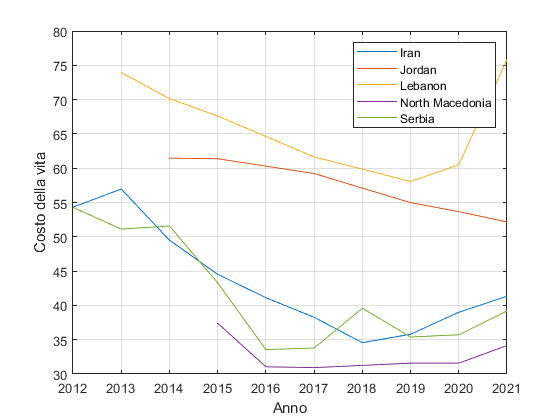

plot(T_pos.Anno(1:presenze_pos(1)),T_pos.CostoDellaVita(1:presenze_pos(1)))
grid on
hold on
%...Inizializzo l'indice della nuova tabella a 10 cosi tengo conto della prima
%...osservazione
table_2_index=presenze_pos(1);
%...Inizializzo una variabile con il numero di osservazioni
for ii=2:length(nazioni_pos)
plot(T_pos.Anno(table_2_index+1:table_2_index+presenze_pos(ii)),T_pos.CostoDellaVita(table_2_index+1:table_2_index+presenze_pos(ii)))
%...Aggiorno l'indice della tabella
table_2_index=table_2_index+presenze_pos(ii);
xlabel("Anno")
ylabel("Costo della vita")
end
hold off
legend(string(nazioni_pos));

5)Potere d'acquisto Immobiliare

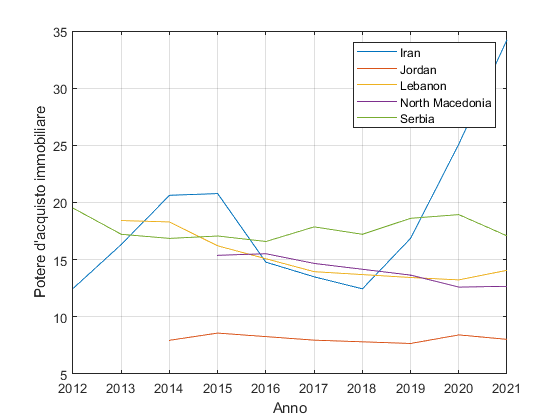

plot(T_pos.Anno(1:presenze_pos(1)),T_pos.PotereDacquistoImmobiliare(1:presenze_pos(1)))
grid on
hold on
%...Inizializzo l'indice della nuova tabella a 10 cosi tengo conto della prima
%...osservazione
table_2_index=presenze_pos(1);
%...Inizializzo una variabile con il numero di osservazioni
for ii=2:length(nazioni_pos)
plot(T_pos.Anno(table_2_index+1:table_2_index+presenze_pos(ii)),T_pos.PotereDacquistoImmobiliare(table_2_index+1:table_2_index+presenze_pos(ii)))
%...Aggiorno l'indice della tabella
table_2_index=table_2_index+presenze_pos(ii);
xlabel("Anno")
ylabel("Potere d'acquisto immobiliare")
end
hold off
legend(string(nazioni_pos));

6) Sicurezza

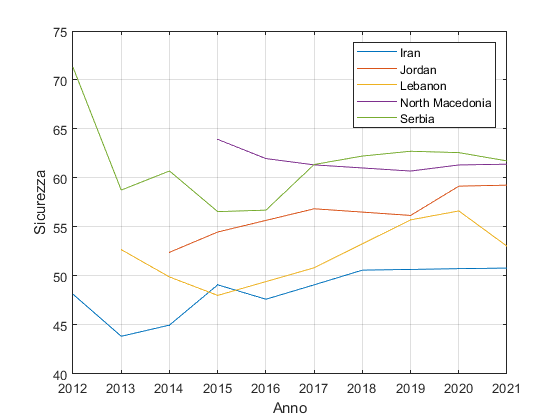

plot(T_pos.Anno(1:presenze_pos(1)),T_pos.Sicurezza(1:presenze_pos(1)))
grid on
hold on
%...Inizializzo l'indice della nuova tabella a 10 cosi tengo conto della prima
%...osservazione
table_2_index=presenze_pos(1);
%...Inizializzo una variabile con il numero di osservazioni
for ii=2:length(nazioni_pos)
plot(T_pos.Anno(table_2_index+1:table_2_index+presenze_pos(ii)),T_pos.Sicurezza(table_2_index+1:table_2_index+presenze_pos(ii)))
%...Aggiorno l'indice della tabella
table_2_index=table_2_index+presenze_pos(ii);
xlabel("Anno")
ylabel("Sicurezza")
end
hold off
legend(string(nazioni_pos));

#### Trend negativi

Ripeto lo stesso procedimento con i trend negativi

1) Salute

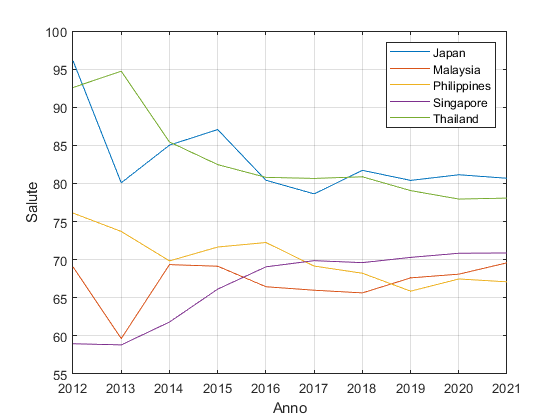

plot(T_neg.Anno(1:presenze_neg(1)),T_neg.Salute(1:presenze_neg(1)))
grid on
hold on
%...Inizializzo l'indice della nuova tabella a 10 cosi tengo conto della prima
%...osservazione
table_2_index=presenze_neg(1);
%...Inizializzo una variabile con il numero di osservazioni
oss=10;
for ii=2:length(nazioni_neg)
plot(T_neg.Anno(table_2_index+1:table_2_index+presenze_neg(ii)),T_neg.Salute(table_2_index+1:table_2_index+presenze_neg(ii)))
%...Aggiorno l'indice della tabella
table_2_index=table_2_index+presenze_neg(ii);
xlabel("Anno")
ylabel("Salute")
end
hold off
legend(string(nazioni_neg));

2) Inquinamento

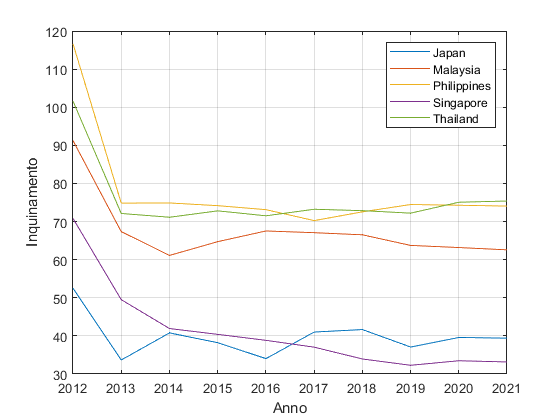

plot(T_neg.Anno(1:presenze_neg(1)),T_neg.Inquinamento(1:presenze_neg(1)))
grid on
hold on
%...Inizializzo l'indice della nuova tabella a 10 cosi tengo conto della prima
%...osservazione
table_2_index=presenze_neg(1);
%...Inizializzo una variabile con il numero di osservazioni
for ii=2:length(nazioni_neg)
plot(T_neg.Anno(table_2_index+1:table_2_index+presenze_neg(ii)),T_neg.Inquinamento(table_2_index+1:table_2_index+presenze_neg(ii)))
%...Aggiorno l'indice della tabella
table_2_index=table_2_index+presenze_neg(ii);
xlabel("Anno")
ylabel("Inquinamento")
end
hold off
legend(string(nazioni_neg));

3) Clima

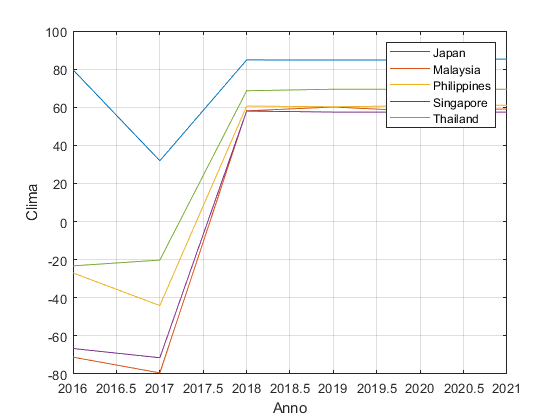

plot(T_neg.Anno(1:presenze_pos(1)),T_neg.Clima(1:presenze_neg(1)))
grid on
hold on
%...Inizializzo l'indice della nuova tabella a 10 cosi tengo conto della prima
%...osservazione
table_2_index=presenze_neg(1);
%...Inizializzo una variabile con il numero di osservazioni
for ii=2:length(nazioni_neg)
plot(T_neg.Anno(table_2_index+1:table_2_index+presenze_neg(ii)),T_neg.Clima(table_2_index+1:table_2_index+presenze_neg(ii)))
%...Aggiorno l'indice della tabella
table_2_index=table_2_index+presenze_neg(ii);
xlabel("Anno")
ylabel("Clima")
end
hold off
legend(string(nazioni_neg));

4) Costo della vita

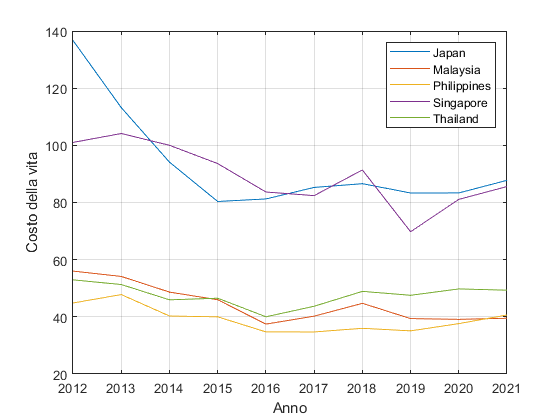

plot(T_neg.Anno(1:presenze_neg(1)),T_neg.CostoDellaVita(1:presenze_neg(1)))
grid on
hold on
%...Inizializzo l'indice della nuova tabella a 10 cosi tengo conto della prima
%...osservazione
table_2_index=presenze_neg(1);
%...Inizializzo una variabile con il numero di osservazioni
for ii=2:length(nazioni_neg)
plot(T_neg.Anno(table_2_index+1:table_2_index+presenze_neg(ii)),T_neg.CostoDellaVita(table_2_index+1:table_2_index+presenze_neg(ii)))
%...Aggiorno l'indice della tabella
table_2_index=table_2_index+presenze_neg(ii);
xlabel("Anno")
ylabel("Costo della vita")
end
hold off
legend(string(nazioni_neg));

5)Potere d'acquisto Immobiliare

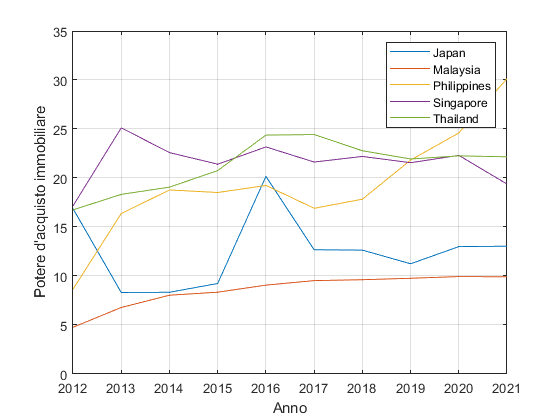

plot(T_neg.Anno(1:presenze_neg(1)),T_neg.PotereDacquistoImmobiliare(1:presenze_neg(1)))
grid on
hold on
%...Inizializzo l'indice della nuova tabella a 10 cosi tengo conto della prima
%...osservazione
table_2_index=presenze_neg(1);
%...Inizializzo una variabile con il numero di osservazioni
for ii=2:length(nazioni_neg)
plot(T_neg.Anno(table_2_index+1:table_2_index+presenze_neg(ii)),T_neg.PotereDacquistoImmobiliare(table_2_index+1:table_2_index+presenze_neg(ii)))
%...Aggiorno l'indice della tabella
table_2_index=table_2_index+presenze_neg(ii);
xlabel("Anno")
ylabel("Potere d'acquisto immobiliare")
end
hold off
legend(string(nazioni_neg));

6) Sicurezza

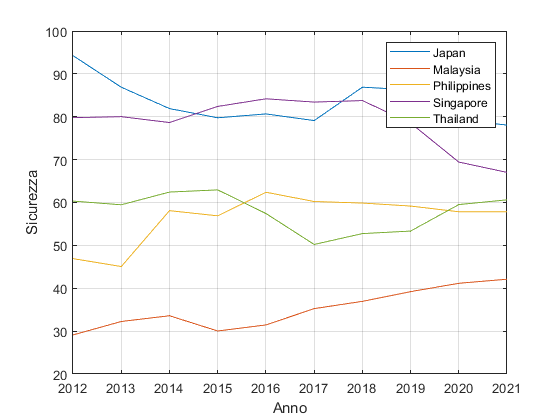

plot(T_pos.Anno(1:presenze_neg(1)),T_neg.Sicurezza(1:presenze_neg(1)))
grid on
hold on
%...Inizializzo l'indice della nuova tabella a 10 cosi tengo conto della prima
%...osservazione
table_2_index=presenze_neg(1);
%...Inizializzo una variabile con il numero di osservazioni
for ii=2:length(nazioni_neg)
plot(T_neg.Anno(table_2_index+1:table_2_index+presenze_neg(ii)),T_neg.Sicurezza(table_2_index+1:table_2_index+presenze_neg(ii)))
%...Aggiorno l'indice della tabella
table_2_index=table_2_index+presenze_neg(ii);
xlabel("Anno")
ylabel("Sicurezza")
end
hold off
legend(string(nazioni_neg));

#### Conclusioni

Secondo l'analisi dei dati ottenuti è emerso che le 5 Nazioni che hanno un andamento che non è peggiorato sono 

nazioni_pos

nazioni_pos = 5×1 categorical array
     Iran 
     Jordan 
     Lebanon 
     North Macedonia 
     Serbia 


Bisogna però tenere conto del fatto che nell'analisi appena fatta si tiene conto solo delle variazioni e non dei valori di partenza, per questo sono presenti Nazioni come Iran o Giordania, che notoriamente non sono le più virtuose.

Per quanto riguarda  le 5 nazioni con le variazioni più disastrose ci sono

nazioni_neg

nazioni_neg = 5×1 categorical array
     Japan 
     Malaysia 
     Philippines 
     Singapore 
     Thailand 


Il cui andamento è polarizzato dall' indice sul clima che è drasticamente aumentato negli anni. Potrebbe essere semplicemente cambiato il modo in cui viene misurato, questo falserebbe la veridicià dell'analisi, per cui si dovrebbe rieffettuare il calcolo del vettore con i plot senza tenerne conto. Se non fosse così, escludere l'indice polarizzerebbe completamente il risultato. Inoltre la ben nota estremizzazione delle condizioni climatiche nel mondo fa pensare che sia possibile che la variazione netta sia sensata.

Kilian Tiziano Le Creurer

Matricola 934596